clc; clearvars;
addpath(genpath("C:\Users\tely1\OneDrive\Desktop\EEJ9903\signal_analysis\functions"));
addpath(genpath("C:\Users\tely1\OneDrive\Desktop\EEJ9903\signal_analysis\overlap_functions"));

Basic parameters

h = planckConstant;
c = physconst("LightSpeed");

navg = 1200; % Number of laser shots being averaged

lambda_287 = 287.2e-9; % wavelength of light in meters
lambda_299 = 299.1e-9; % wavelength of light in meters

E0_287 = 10.6e-3; % Laser pulse energy in joules
E0_299 = 6.3e-3; % Laser pulse energy in joules

eta_287 = 0.005; % Efficiency factor (excluding quantum efficiency)
eta_299 = 0.0028; % Efficiency factor (excluding quantum efficiency)

etaR = 0.1; % Receiver Efficiency
etaQ = 0.7; % Quantum efficiency

t_r = .2;   % Radius of the receiver in meters
o_r = 0.1;  % Radius of the obstruction
tau = 1/40e6; % sampling length

f = 1.905; % telescope focal length in meters
a = 0.002; % aperture_radius in meters
za = 0; % distance between focal plane and aperture

delta = 0; % distance between receiver and transmitter axes
w0 = 0.0045; % laser beam waist in meters (radius at laser exit)
phi0 = 0.000167; % laser divergence angle (half angle)
phi1 = a/(f+za); % Receiver opening angle/FOV in radians (half angle)
beam_profile = "gaussian"; % Laser beam profile shape

A = pi*(t_r^2 - o_r^2); % Receiver area accounting for obstruction in m^2
Omega = phi1^2 * pi; % Receiver FOV in steradian (ph1 is half angle)

Altitude grid

alt_inst = 20; % altitude of lidar in meters
alt = (alt_inst:10:30e3)'; % altitude grid to perform calculations in meters
alt_km = alt./1e3; % altitude grid for plotting in kilometers

Ozone Number Density

O3_data = load("C:\Users\tely1\OneDrive\Matlab Onedrive\O3_Lidar\sample_result\o3_lidar_20250919.mat");

N_O3 = O3_data.result.No3_merged;
n_o3_prof = size(N_O3,2);
l_o3 = size(N_O3,1);
id1 = 1;
id2 = 12;

N_O3 = interp1((1:l_o3).*3.75,N_O3(:,id1:id2),alt);
N_O3 = fillmissing(N_O3,"constant",0);

Ozone Absorption Cross Section

BDM = load("C:\Users\tely1\OneDrive\Desktop\EEJ9903\signal_analysis\cross_sections\ozone\bdm\bdm_287_299.mat");

sigma_o3_287 = BDM.BDM_c287(1) .* 1e-4; % use first temp dependent cross section for now
sigma_o3_299 = BDM.BDM_c299(1) .* 1e-4; % use first temp dependent cross section for now

Air Number Density

Nair = airNumberDensity(alt);

Overlap Function

overlap_params = struct;
overlap_params.alt = alt;
overlap_params.w0 = w0;
overlap_params.phi0 = phi0;
overlap_params.a = a;
overlap_params.o_r = o_r;
overlap_params.t_r = t_r;
overlap_params.f = f;
overlap_params.za = za;
overlap_params.delta = delta;
overlap_params.beam_profile = beam_profile;

overlap_data_path = "./overlap_data.mat";
if exist(overlap_data_path,"file")
    overlap_data = load(overlap_data_path);

    if isequal(overlap_params, overlap_data.overlap_params_save)
        O = overlap_data.O; % Load the pre-computed overlap function
        disp("unchanged")
    else
        O = overlapFunc(alt, w0, phi0, a, o_r, t_r, f, za, delta, beam_profile);
        disp("changed")
    end
else
    O = overlapFunc(alt, w0, phi0, a, o_r, t_r, f, za, delta, beam_profile);
end

unchanged


overlap_params_save = overlap_params;
save(overlap_data_path,"O","overlap_params_save");

Background signal

load("C:\Users\tely1\OneDrive\Desktop\EEJ9903\signal_analysis\bg_data.mat");

BW = 5e-9; % Filter bandwidth in meters (?)

[NB_287, CB_287] = background(lambda_287,A,tau,etaR,BW,phi1,L_287_avg);
[NB_299, CB_299] = background(lambda_299,A,tau,etaR,BW,phi1,L_299_avg);

Calculate the signal

NS_287 = signal(alt,lambda_287,E0_287,A,tau,eta_287,etaQ,Nair,sigma_o3_287,N_O3,O); 
NS_299 = signal(alt,lambda_299,E0_299,A,tau,eta_299,etaQ,Nair,sigma_o3_299,N_O3,O); 

[N_287, N_nsy_287] = add_noise(NS_287,NB_287,navg);
[N_299, N_nsy_299] = add_noise(NS_299,NB_299,navg);

C_287 = convert_to_countrate(NS_287,tau);
C_299 = convert_to_countrate(NS_299,tau);

C_nsy_287 = convert_to_countrate(N_nsy_287,tau);
C_nsy_299 = convert_to_countrate(N_nsy_299,tau);

C_grid = alt;
save("C.mat","C*");

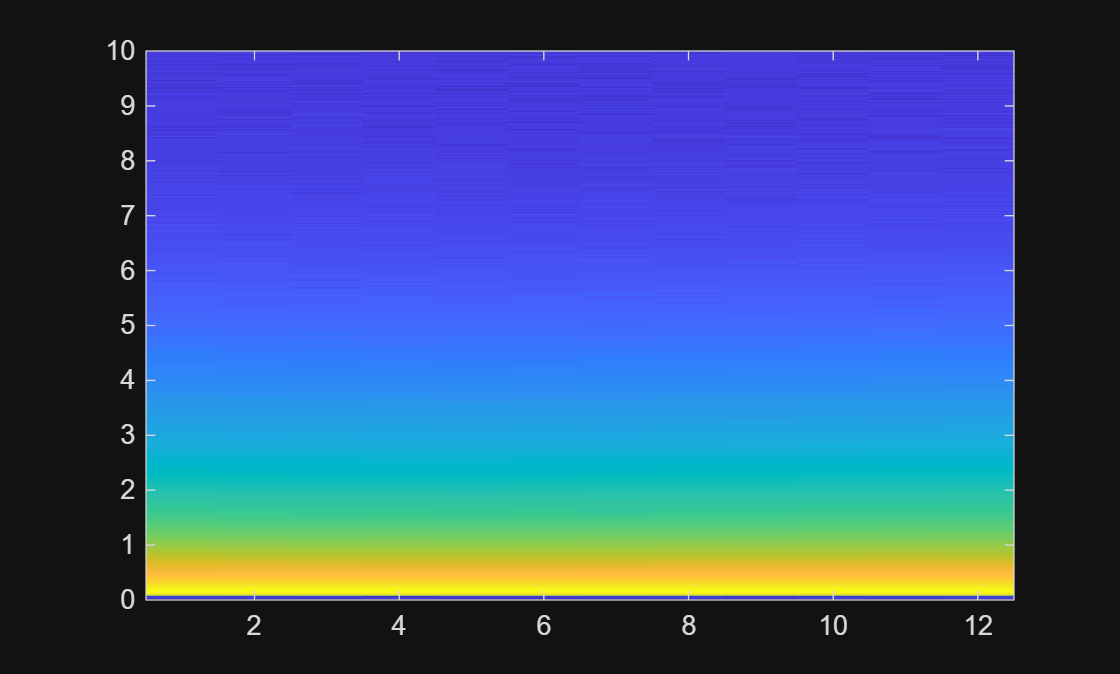

figure;
imagesc((id1:id2),alt_km,log10(C_nsy_287))
set(gca, 'YDir','Normal')
% set(gca, 'YScale','log')
ylim([0 10])

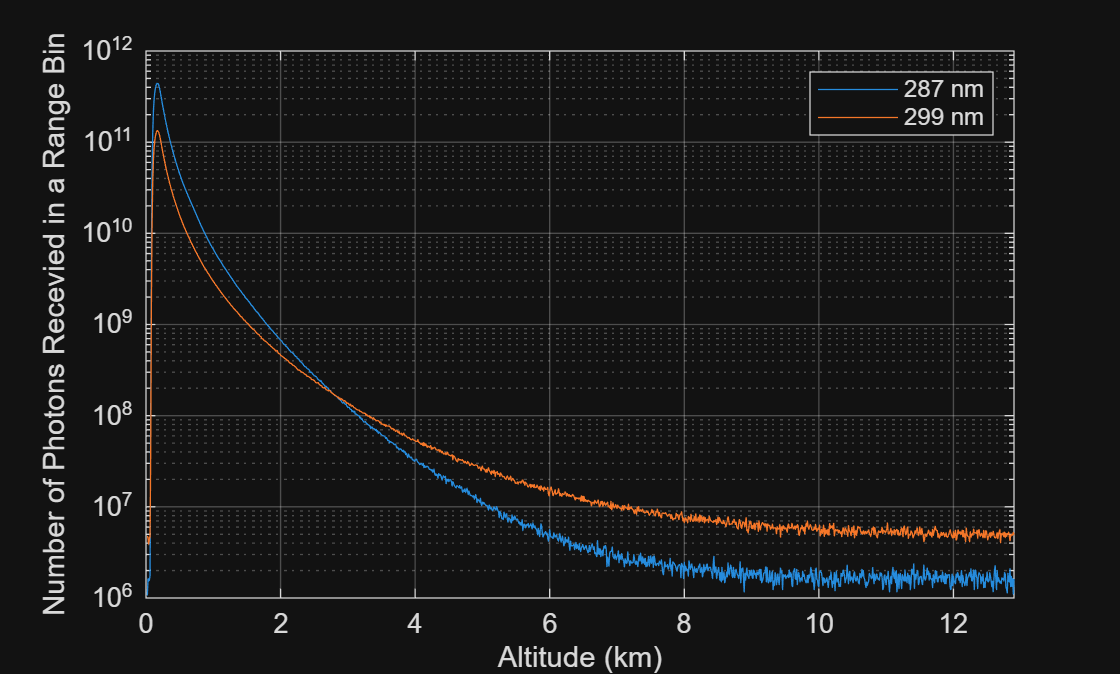

id_plt = 1;
x_lim =[0 12.9];

figure;
semilogy(alt_km, C_nsy_287(:,id_plt), 'DisplayName',"287 nm")
hold on
plot(alt_km, C_nsy_299(:,id_plt), 'DisplayName',"299 nm")
hold off
xlabel("Altitude (km)")
ylabel("Number of Photons Recevied in a Range Bin")
xlim(x_lim)
grid on
legend

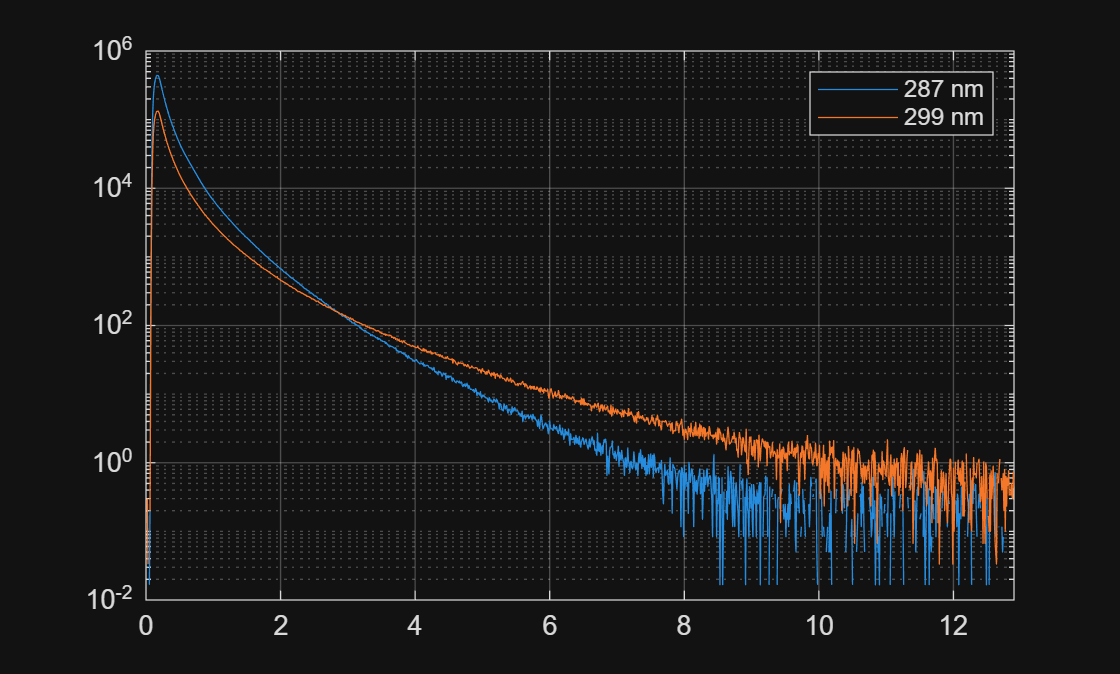

figure;
semilogy(alt_km,(C_nsy_287(:,id_plt)-CB_287).*1e-6,'DisplayName','287 nm');
hold on
plot(alt_km,(C_nsy_299(:,id_plt)-CB_299).*1e-6,'DisplayName','299 nm');
hold off
xlim(x_lim)
grid on
legend

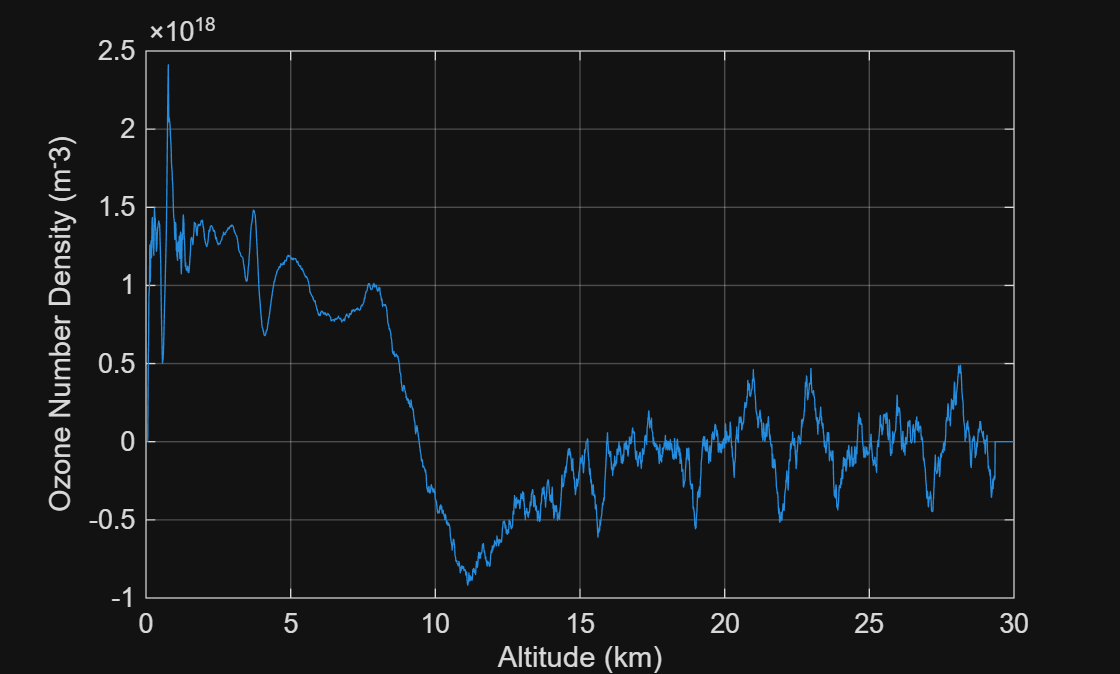

figure;
plot(alt_km,N_O3(:,id_plt));
xlabel("Altitude (km)")
ylabel("Ozone Number Density (m^-3)")
grid on

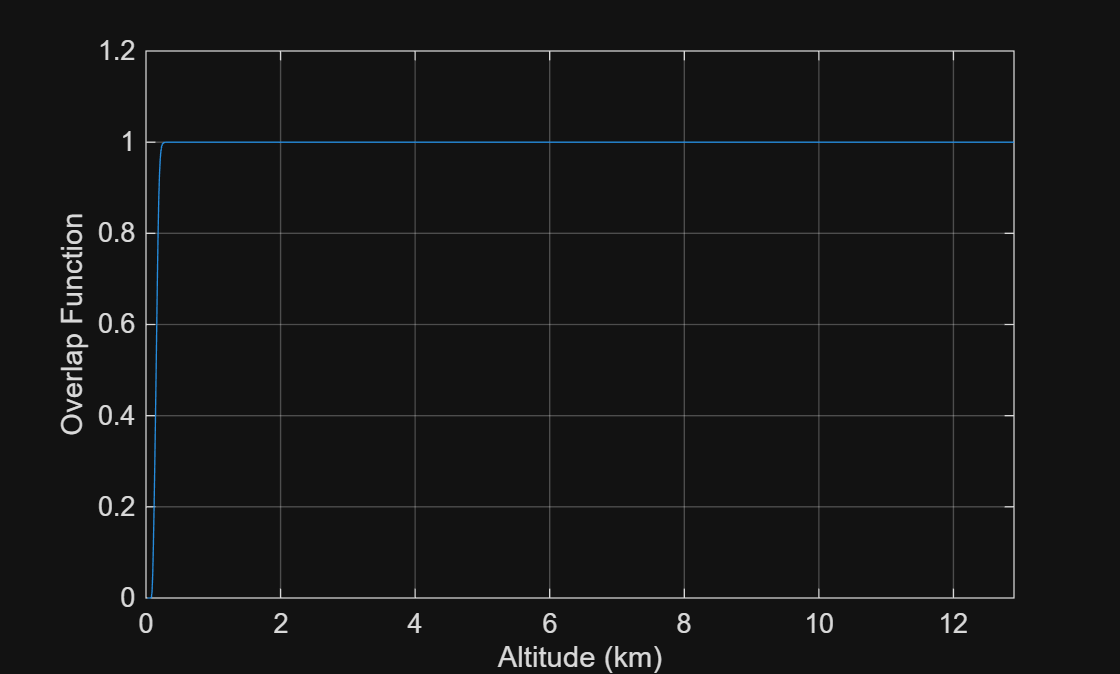

figure;
plot(alt_km,O)
xlabel("Altitude (km)")
ylabel("Overlap Function")
grid on
xlim(x_lim)